syms v_x omega_x omega_y omega_z
syms t % Time variabel
syms n_omega % Norm of omega
assume([v_x omega_x omega_y omega_z], "real")
assume(t, ["real", "positive"])
assume(n_omega, ["real", "positive"])

muscle_o = Muscle3D(0.1, 0);

v = [v_x, 0, 0]';
omega = [omega_x, omega_y, omega_z]';
h = [v; omega];
m = expm_se3([v; omega]*t);
m(1:3, 4)

$$ans = \begin{array}{l} \left(\begin{array}{c} t\,v_{x}\,\left(\frac{\sigma_{1}\,\left({\omega_{y}}^{2}\,t^{2}+{\omega_{z}}^{2}\,t^{2}\right)}{{\sigma_{3}}^{3/2}}+1\right)\\ -t\,v_{x}\,\left(\frac{\omega_{z}\,t\,\sigma_{2}}{\sigma_{3}}+\frac{\omega_{x}\,\omega_{y}\,t^{2}\,\sigma_{1}}{{\sigma_{3}}^{3/2}}\right)\\ t\,v_{x}\,\left(\frac{\omega_{y}\,t\,\sigma_{2}}{\sigma_{3}}-\frac{\omega_{x}\,\omega_{z}\,t^{2}\,\sigma_{1}}{{\sigma_{3}}^{3/2}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\sqrt{\sigma_{3}}\right)-\sqrt{\sigma_{3}}\\ \sigma_{2}=\cos\left(\sqrt{\sigma_{3}}\right)-1\\ \sigma_{3}=t^{2}\,{\left|\omega_{x}\right|}^{2}+t^{2}\,{\left|\omega_{y}\right|}^{2}+t^{2}\,{\left|\omega_{z}\right|}^{2} \end{array}$$

v = [v_x, 0, 0]';
omega = [0 omega_y 0]';
h = [v; omega];
m = expm_se3([v; omega]*t);
r = simplify(m(1:3, 4))

$$r = \left(\begin{array}{c} \frac{v_{x}\,\left(t\,{\left|\omega_{y}\right|}^{3}+{\omega_{y}}^{2}\,\sin\left(t\,\left|\omega_{y}\right|\right)-{\omega_{y}}^{2}\,t\,\left|\omega_{y}\right|\right)}{{\left|\omega_{y}\right|}^{3}}\\ 0\\ \frac{v_{x}\,\left(\cos\left(t\,\left|\omega_{y}\right|\right)-1\right)}{\omega_{y}} \end{array}\right)$$

r_simplified = v_x / omega_y * [sin(omega_y*t); 0; cos(omega_y*t) - 1]

$$r\_simplified = \left(\begin{array}{c} \frac{v_{x}\,\sin\left(\omega_{y}\,t\right)}{\omega_{y}}\\ 0\\ \frac{v_{x}\,\left(\cos\left(\omega_{y}\,t\right)-1\right)}{\omega_{y}} \end{array}\right)$$

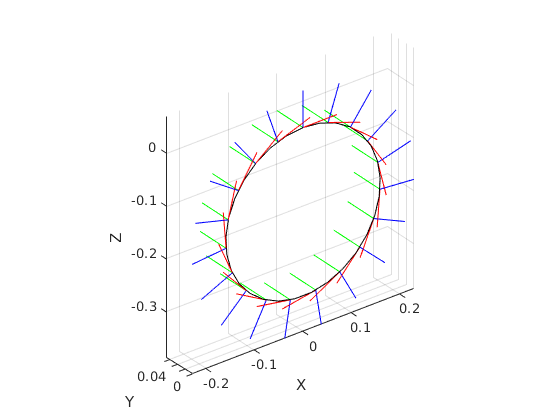


muscle_o.h_tilde = [1; 0; 0; 0; 2*pi; 0];

fig = figure();

view(10, 10)
grid on
axis equal
xlabel("X")
ylabel("Y")
zlabel("Z")

[~, g_muscle] = muscle_o.plot_muscle(resolution=30);
gh_tforms = muscle_o.plot_tforms(g_muscle=g_muscle, plot_options=struct('FrameSize', 0.07));

## Planar Spiral

Spiral on a 2d plane

v = [v_x, 0, 0]';
omega = [omega_x omega_y 0]';
h = [v; omega];

% Analytic formula for pose matrix over time
m = expm_se3([v; omega]*t);

% We only care about the position
r = simplify(m(1:3, 4));
r_t = subs(r, simplify(norm(omega)), n_omega)

$$r\_t = \left(\begin{array}{c} \frac{v_{x}\,\left(n_{\omega }\,t\,{\omega_{x}}^{2}+\sin\left(n_{\omega }\,t\right)\,{\omega_{y}}^{2}\right)}{{n_{\omega }}^{3}}\\ -\frac{\omega_{x}\,\omega_{y}\,v_{x}\,\left(\sin\left(n_{\omega }\,t\right)-n_{\omega }\,t\right)}{{n_{\omega }}^{3}}\\ \frac{\omega_{y}\,v_{x}\,\left(\cos\left(n_{\omega }\,t\right)-1\right)}{{n_{\omega }}^{2}} \end{array}\right)$$

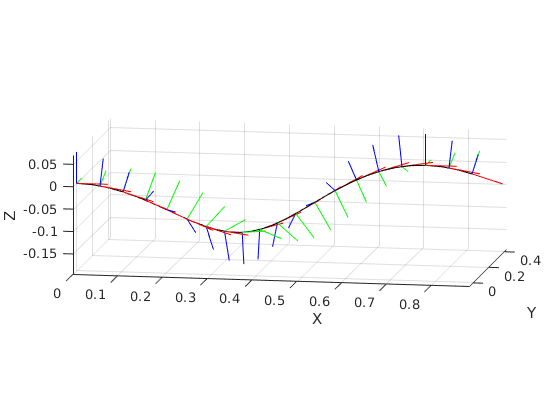


% Numeric trajectory calculation:
v_val = [1; 0; 0];
omega_val = [2*pi; pi; 0];
muscle_o.h_tilde = [v_val; omega_val];

% Plotting
fig = figure();
clf

view(10, 10)
hold on
grid on
axis equal
xlabel("X")
ylabel("Y")
zlabel("Z")

[~, g_muscle] = muscle_o.plot_muscle(resolution=30);

tform_options = struct('FrameSize', 0.07);
gh_tforms = muscle_o.plot_tforms(g_muscle=g_muscle, plot_options=tform_options);

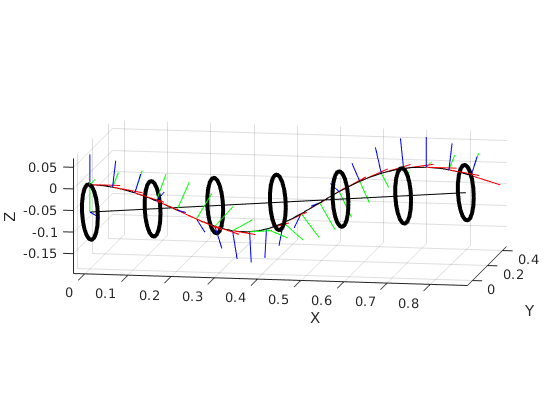

% Verifying the analytic re-parameterization
o_z = -omega_val(2) * v_val(1)/norm(omega_val)^2;

omega_star = norm(omega_val);
ax = omega_val / norm(omega_val);
rho = v_val(1)*omega_val(2) / norm(omega_val)^2;

v_x_prime = omega_val(1) * v_val(1) / norm(omega_val);

R_circle = [ax [0; 0; 1] cross(ax, [0; 0; 1])];
g_offset = SE3(eul2rotm([0, -pi/2, 0], 'xyz'), [0; 0; 0]);
g_circle_0 = SE3(R_circle, [0; 0; o_z]);

plotTransforms([0 0 o_z], rotm2quat(R_circle), tform_options);

n_circles = 7;
t_circles = linspace(0, 1, n_circles);
v_circle = [v_x_prime; 0; 0];
for i = 1 : length(t_circles)
    g_circle_i =  g_circle_0 * SE3(eye(3), v_circle*t_circles(i)) * g_offset;
    plot_circle(line(0, 0, 0, 'color', 'k', 'linewidth', 3), rho, g_circle_i);
end
muscle_winding_axis = Muscle3D(v_circle(1), [0;0;0], 'g_0', g_circle_0);
muscle_winding_axis.plot_muscle();

## Spatial Spiral

Spiral in 3D space

v = [v_x, 0, 0]';
omega = [omega_x omega_y omega_z]';
h = [v; omega];

% Analytic formula for pose matrix over time
m = expm_se3(h*t);

% We only care about the position
r = simplify(m(1:3, 4));
r_t = subs(r, simplify(norm(omega)), n_omega);
r_t = simplify(r_t)

$$r\_t = \begin{array}{l} \left(\begin{array}{c} t\,v_{x}\,\left(\frac{\sigma_{1}\,\left({\omega_{y}}^{2}+{\omega_{z}}^{2}\right)}{{n_{\omega }}^{3}\,t}+1\right)\\ -t\,v_{x}\,\left(\frac{\omega_{z}\,\sigma_{2}}{{n_{\omega }}^{2}\,t}+\frac{\omega_{x}\,\omega_{y}\,\sigma_{1}}{{n_{\omega }}^{3}\,t}\right)\\ t\,v_{x}\,\left(\frac{\omega_{y}\,\sigma_{2}}{{n_{\omega }}^{2}\,t}-\frac{\omega_{x}\,\omega_{z}\,\sigma_{1}}{{n_{\omega }}^{3}\,t}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(n_{\omega }\,t\right)-n_{\omega }\,t\\ \sigma_{2}=\cos\left(n_{\omega }\,t\right)-1 \end{array}$$

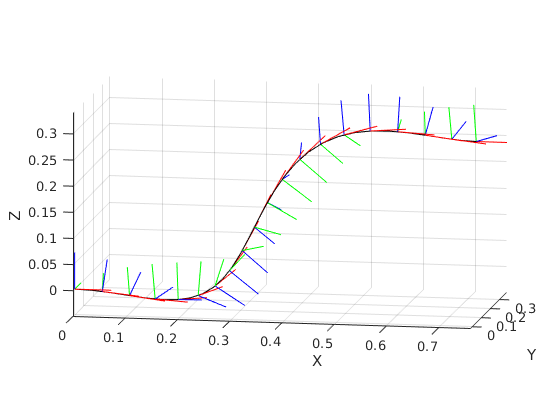


% Numeric trajectory calculation:
v_val = [1; 0; 0];
omega_val = [2*pi; pi; pi];
muscle_o.h_tilde = [v_val; omega_val];

% Plotting
fig = figure();
clf

view(10, 10)
hold on
grid on
axis equal
xlabel("X")
ylabel("Y")
zlabel("Z")

[~, g_muscle] = muscle_o.plot_muscle(resolution=30);

gh_tforms = muscle_o.plot_tforms(g_muscle=g_muscle, plot_options=struct('FrameSize', 0.07));

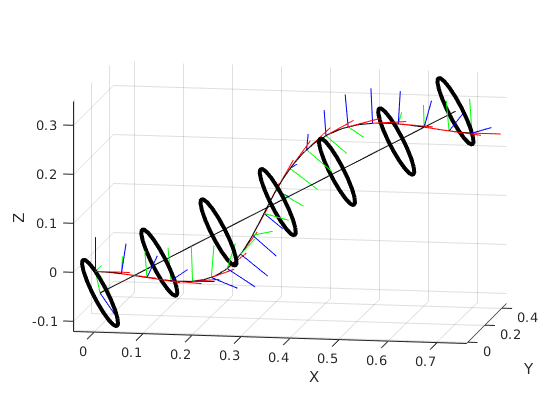

% Analytic spatial curve reparameterization
ax = omega_val / norm(omega_val);
o = mat_skew_sym(omega_val) * v_val / norm(omega_val)^2;
rho = norm(o);

v_x_prime = omega_val(1) * v_val(1) / norm(omega_val);

% The winding axis, and the vector from the starting position to the circle
% center should be orthogonal on the plane they share (the circle). We can
% use this to find the third orthogonal basis vector (cross product), and
% use this to construct the rotation matrix for the orientation of the
% helix base.
R_circle = [ax -o/norm(o) cross(ax, -o/norm(o))];

g_offset = SE3(eul2rotm([0, -pi/2, 0], 'xyz'), [0; 0; 0]);
g_circle_0 = SE3(R_circle, o);

plotTransforms(o', rotm2quat(R_circle), tform_options);

n_circles = 7;
t_circles = linspace(0, 1, n_circles);
v_circle = [v_x_prime; 0; 0];
for i = 1 : length(t_circles)
    g_circle_i =  g_circle_0 * SE3(eye(3), v_circle*t_circles(i)) * g_offset;
    plot_circle(line(0, 0, 0, 'color', 'k', 'linewidth', 3), rho, g_circle_i);
end
muscle_winding_axis = Muscle3D(v_circle(1), [0;0;0], 'g_0', g_circle_0);
muscle_winding_axis.plot_muscle();